## Basic Vizualization

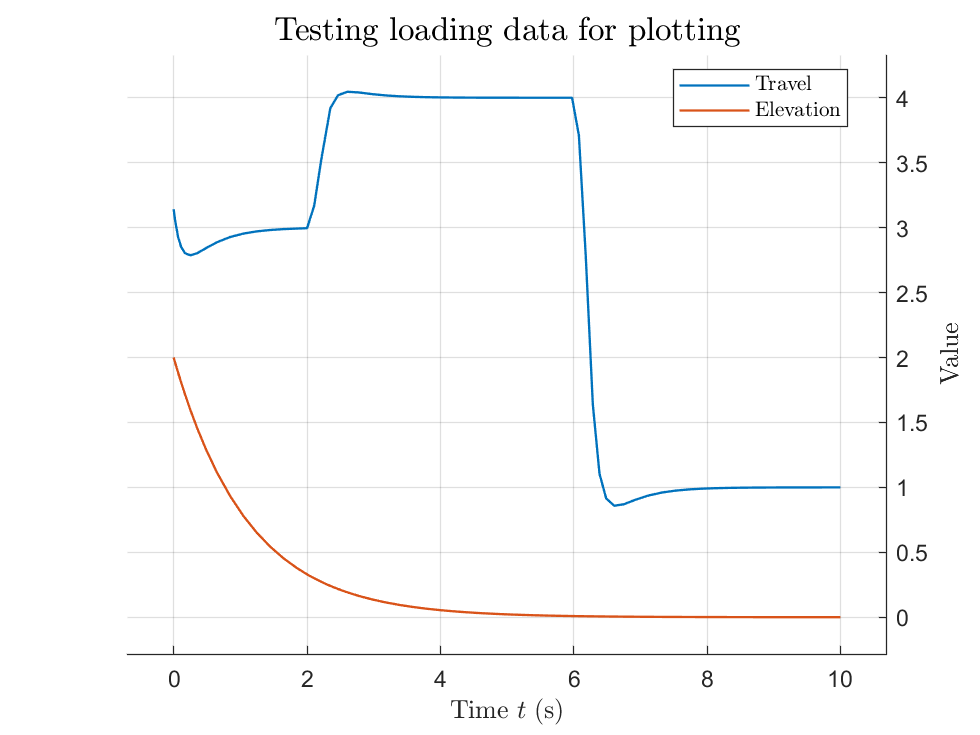

% Load data from MAT-file into workspace 
test_timeseries = load("testRun1.mat");
sim_data = test_timeseries.testRun1;

time_data = sim_data(1, :);
travel_data = sim_data(2, :);
elevation_data = sim_data(3, :);

% Setup gca 
figure(); grid on; hold on
set(gca,'YAxisLocation','right')
axis padded

% Plot data
plot(time_data, travel_data,"linewidth", 1,"linestyle","-");
plot(time_data, elevation_data,"linewidth", 1,"linestyle","-");

% Set title, labels and legends
title("Testing loading data for plotting", "Interpreter", "latex", 'fontweight','bold', "FontSize", 14)
legend(["Travel" "Elevation"], "Location", "best", "Interpreter", "latex")
xlabel("Time $t$ (s)","Interpreter","latex")
ylabel("Value" , "Interpreter","latex")

% Cleanup gca 
hold off


% Write gca to File (jpg, png, eps, etc....) 
saveas(gcf, "testRun1.eps")